# AAE 567 HW4 Problem4

% Housekeeping commands
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
outdir = pwd + "\output\hw4";
mdir = pwd + "\mfiles\hw4";

m = 2;
% Define expectations 
syms x y
g = [];
for n = 0:m
    g = [g; y^n];
end
yl = 0; yu = 1;  % range of y
xl = 0; xu = 1; % range of x
fy = 1 ;

EY = @(A) int(y.^A, yl, yu);
EX = @(A) int(expm(A*y), yl, yu);
EXY = @(A,B) int(y.^B .* expm(A*y), yl, yu);

% P_Hx
Rfg = EXY(1, 0:m);
A = [];
for n = 0:m
    A = [A; n:n+m];
end
Rg = EY(A);

coef = Rfg * inv(Rg);
coef = eval(coef);
% Error d4
d4sq = EX(2) - Rfg*inv(Rg)*Rfg'

$$d4sq = 2.7835e-05$$

d4 = sqrt(d4sq);

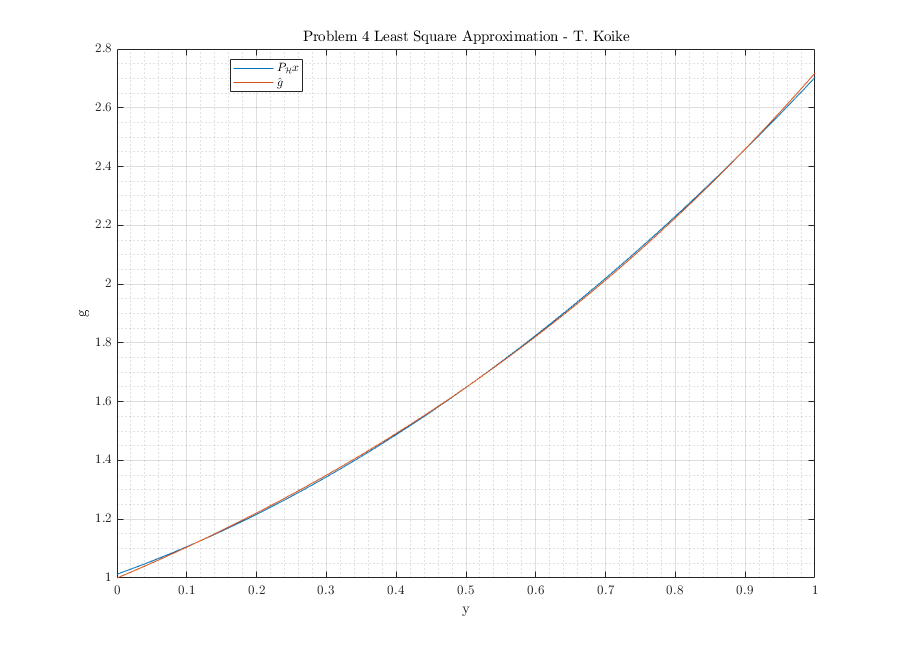

% Plotting
t = 0:0.01:1;
% ghat
Phx = 0;
for n = 1:length(coef)
    Phx = Phx + coef(n)*t.^(n-1);
end

fig = figure("Renderer","painters",'Position',[60 60 900 650]);
    plot(t, Phx)
    grid on; grid minor; box on; hold on;
    plot(t, exp(t))
    hold off;
    title('Problem 4 Least Square Approximation - T. Koike')
    legend('$P_{\mathcal{H}}x$', '$\hat{g}$', "Location","best")
    xlabel('y')
    ylabel('g')
saveas(fig, fullfile(outdir, 'p4_lsqr_plot.png'));

% Save file as .m
matlab.internal.liveeditor.openAndConvert('hw4_p4.mlx', ...
    convertStringsToChars(fullfile(mdir, 'hw4_p4.m')));